# Black box Approach for Synchronization - tube 

For each animal, select one match from all other animals based on event time/coverage, then assess the accuracy of selection. 

Since many animals do not have long events, this analysis is based on 5s and 20s events only. 

1 remove events that start within 15s after the start of the trials.

2 for each animal calculate its event coverage.

3 select random 400s interval from each pair with event coverage in both animals closest to 20%. 

4 for each animal select its match based on highest overlap in coverage.

5 rank all animals according to percentage overlap, find the rank for the correct corresponding pair. 

6 for each animal select its match based on highest population rate correlation 

#### Data preparation

% get simplified events
load('em_18p_th0.5.mat')
load('dTT_SYN_18Pair_R3_10032020.mat')
em=rem_dup_em(em); % remove duplication in M 
[N,nm]=size(em{1,1}.eve);
klist={5,20};% find 5s events 
for r=1:2 % two rounds 
    allt=cell(N,nm);allm=cell(N,nm);allk=cell(N,nm);
    for p=1:N
        for m=1:nm
            [allt{p,m},allm{p,m},allk{p,m}]=alltmk(klist,em{r,1}.K{p,m},em{r,1}.M{p,m},em{r,1}.time{p,m});
        end
    end
    em{r,1}.allt=allt;em{r,1}.allm=allm;em{r,1}.klist=klist;em{r,1}.allk=allk;
end

#### Step 1 

% merge events from the two rounds of detection 
ev_merge=cell(N,nm); % start time of all events 
for p=1:N
    for m=1:nm
        ev_merge{p,m}=cell(1,length(klist));
        for k=1:length(klist)
            ev_merge{p,m}{k}=em{1,1}.allt{p,m}{k};
            filt=find(em{2,1}.timefilter{p,m}); % timefilter for second round  
            ev_merge{p,m}{k}=[ev_merge{p,m}{k},filt(em{2,1}.allt{p,m}{k})];
            ev_merge{p,m}{k}=remove_time_ovp(ev_merge{p,m}{k},klist{k}); % remove highly overlapped events
            % remove events around onsets 
            totalt=size(em{1,1}.ca_cl{p,m},2);
            onset = find(sum(reshape(E{p}{1}.BehaviorVectors(1:30*totalt,4),30,totalt),1)); 
            ev_merge{p,m}{k}=remove_onset(ev_merge{p,m}{k},onset,15);
        end
    end
end

#### Step 2

totalcov=cell(N,nm); % time of event coverage
for p = 1:N
    for m = 1:nm
        [totalcov{p,m}]=evecoverage(size(em{1,1}.ca_cl{p,m},2),ev_merge{p,m},klist);
    end
end

#### Step 3

len=400;start=zeros(1,N);
for p =1:N
    start(p)=floor(250*rand); % start from a random number
    if sum(totalcov{p,1})==0 || sum(totalcov{p,2})==0
        continue
    end
    while sum(totalcov{p,1}(start(p):start(p)+399))==0 || sum(totalcov{p,2}(start(p):start(p)+399))==0
        start(p)=floor(250*rand);
    end
end

#### Step 4-5

r=NaN(N,nm);
for p=1:N
    for m=1:nm
        eves=totalcov{p,m}(start(p):start(p)+len-1);
        evesyn=NaN(N,nm);
        for p0=1:N
            for m0=1:nm
                if p0==p&&m0==m
                    continue
                end
                eveo=totalcov{p0,m0}(start(p0):start(p0)+len-1);
                evesyn(p0,m0)=sum(eves&eveo)/sum(eves);
            end
        end
        [msyn,rank]=sort(evesyn(:),'descend',"MissingPlacement","last"); % 
        if m==1
            r(p,m)=find(rank==p+18);
        else 
            r(p,m)=find(rank==p);
        end
    end
end 

#### Step 6 population rate correlation 

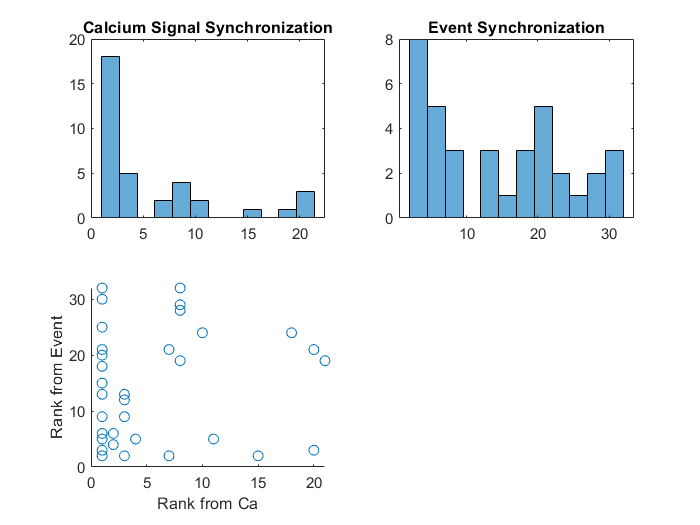

close all
rca=NaN(N,nm);
for p = 1:N
    for m=1:2
        ca=mean(em{1,1}.ca_cl{p,m}(:,start(p):start(p)+len-1));
        casyn=NaN(N,nm);
        for p0=1:N
            for m0=1:nm
                if p0==p&&m0==m
                    continue
                end
                ca2=mean(em{1,1}.ca_cl{p0,m0}(:,start(p0):start(p0)+len-1));
                casyn(p0,m0)=corr2(ca,ca2);
            end
        end
        [msyn,rank]=sort(casyn(:),'descend',"MissingPlacement","last"); % 
        if m==1
            rca(p,m)=find(rank==p+18);
        else 
            rca(p,m)=find(rank==p);
        end
    end
end
subplot(2,2,1)
histogram(rca,12);title('Calcium Signal Synchronization')
subplot(2,2,2)
histogram(r,12); title('Event Synchronization')
subplot(2,2,3)
scatter(rca(:),r(:)); xlabel('Rank from Ca'); ylabel('Rank from Event')

sprintf('correct number from ca:%d',sum(rca(:)==1))

ans = 'correct number from ca:16'

sprintf('correct number from event:%d',sum(r(:)==1))

ans = 'correct number from event:0'